# Sviluppo di un predittore della RUL di motori di aerei

## Il codice procede nel modo seguente: 

- Estrazione dati dei sensori $X_s$ e delle condizioni operative $W$ dai file .h5

- Pretrattamento dati per la determinazione del modello di degradazione con la creazione di un ensamble $[W|X_s]$

- Creazione del modello di degradazione per ogni sensore di $X_s$ con Health Condition

- Creazione di un Health Indicator unico

- Visualizzazione RUL Runtime

- Calcolo dello scostamento tra RUL stimata e vera e visualizzazione dei risultati

## Importo le tabelle con i dati dev e test dal file .h5

clc, close all, clear all
% indicare chi è ad usare il programma, se non compreso tra
% 'Ado','Oleg','Andrea','Giorgio' scegliere dal menu che appare
% automaticamente

user = "";

Selezione del dataset da analizzare

fattore_decim = 90;
numero_dataset = 9;

% creiamo i vettori che contengono i dataset di Training e Test
degradationData = cell(1,numero_dataset);
degradationDataTest = cell(1,numero_dataset);

for indice = 1:numero_dataset
    
    [X_s_time,W_tab_dev,Y_tab_dev,A_tab_dev, T_tab_dev ...
            ,X_s_tab_test, W_tab_test, Y_tab_test, ...
            A_tab_test, T_tab_test] = importoTabelle(indice, user);
    % Decimazione delle tabelle di "learning phase"
    X_dec = decimazione_dati(X_s_time, fattore_decim);
    A_dec = A_tab_dev(1:fattore_decim:end,:);
    W_dec = W_tab_dev(1:fattore_decim:end,:);
    Y_dec = decimazione_dati(Y_tab_dev, fattore_decim);
    T_dec = decimazione_dati(T_tab_dev, fattore_decim);
    
    % Decimazione delle tabelle di test
    Xt_dec = decimazione_dati(X_s_tab_test, fattore_decim);
    At_dec = A_tab_test(1:fattore_decim:end,:);
    Wt_dec = W_tab_test(1:fattore_decim:end,:);
    Yt_dec = decimazione_dati(Y_tab_test, fattore_decim);
    Tt_dec = decimazione_dati(T_tab_test, fattore_decim);
    
    %clearvars -except X_dec A_dec W_dec Y_dec T_dec Xt_dec At_dec Wt_dec Yt_dec Tt_dec degradationData degradationDataTest indice fattore_decim numero_dataset user
    Hs = A_dec.hs;
    Hst = At_dec.hs;
    mista = creamista(X_dec,W_dec);
    mista_test = creamista(Xt_dec,Wt_dec);
    
    % ensamble table dataset di Training
    auxData = GeneraEnsabletable2(Hs,mista);
    degradationData{1,indice} = table2cell(auxData);
    
    % ensamble table dataset di Validation Data
    auxTest = GeneraEnsabletable2(Hst,mista_test);
    degradationDataTest{1,indice} = table2cell(auxTest);

    %clearvars -except degradationData degradationDataTest indice fattore_decim numero_dataset user
end

Error using h5readc
Unable to open 'C:\Users\olegg\Downloads\Progetto_manutenzione_preventiva-main\Progetto_manutenzione_preventiva-main\N-CMAPSS_DS01-005.h5'. File or folder
not found.

Error in h5read (line 93)
[data,var_class] = h5readc(Filename,Dataset,start,count,stride);

Error in mainScriptFinale>importoTabelle (<a href="ma

## CLUSTERING DEI MOTORI IN GRUPPI CON CONDIZIONI OPERATIVE SIMILI (kmeans)

**Preparazione dati ed estrazione **

%pulizia variabili
clearvars -except degradationData degradationDataTest

% estraggo i 60 motori
trainData = vertcat(degradationData{:});
validationData = vertcat(degradationDataTest{:});

OpCondVectorTrain = table('Size',[height(trainData) 4], 'VariableTypes',{'double','double','double','double'}, ...
    'VariableNames',{'alt','Mach','TRA','T2'});

OpCondVectorValid = table('Size',[height(validationData) 4], 'VariableTypes',{'double','double','double','double'}, ...
    'VariableNames',{'alt','Mach','TRA','T2'});

% calcolo media (o mediana) e SD delle OpCond per ogni motore
for motore = 1:height(trainData)
    OpCondVectorTrain.alt(motore) = mean(trainData{motore}.alt);
    OpCondVectorTrain.Mach(motore) = mean(trainData{motore}.Mach);
    OpCondVectorTrain.TRA(motore) = mean(trainData{motore}.TRA);
    OpCondVectorTrain.T2(motore) = mean(trainData{motore}.T2);
end

% calcolo media (o mediana) e SD delle OpCond per ogni motore
for motore = 1:height(validationData)
    OpCondVectorValid.alt(motore) = mean(validationData{motore}.alt);
    OpCondVectorValid.Mach(motore) = mean(validationData{motore}.Mach);
    OpCondVectorValid.TRA(motore) = mean(validationData{motore}.TRA);
    OpCondVectorValid.T2(motore) = mean(validationData{motore}.T2);
end

%Per le OpCond meglio usare la mediana (dei picchi): usare islocalmax() per trovare i picchi

**Creazione dei cluster per  **`trainData`

numCluster = 6;
opts = statset('Display', 'final');
[clusterIndex, centers] = kmeans(table2array(OpCondVectorTrain), numCluster, ...
        'Distance', 'sqeuclidean', 'Replicates', 5, 'Options', opts);

Replicate 1, 1 iterations, total sum of distances = 1.75542e+06.
Replicate 2, 3 iterations, total sum of distances = 1.43009e+06.
Replicate 3, 2 iterations, total sum of distances = 2.17317e+06.
Replicate 4, 1 iterations, total sum of distances = 2.00299e+06.
Replicate 5, 4 iterations, total sum of distances = 2.74494e+06.
Best total sum of distances = 1.43009e+06


** Creazione **`clusterIndex` **per **`validationData`** (stessi centri di **`trainData`**)**

[dist,clusterIndexValid] = pdist2(centers, table2array(OpCondVectorValid), 'euclidean','Smallest',1);

% [clusterIndexValid, centersValid] = kmeans(table2array(OpCondVectorValid), numCluster, ...
%         'Distance', 'sqeuclidean', 'Options', opts, 'start', centers);

**Separazione motori in cluster secondo **`clusterIndex`

sovraClustersTrain = cell(numCluster,1);

for motore = 1:height(trainData)
    sovraClustersTrain{clusterIndex(motore),1}{height(sovraClustersTrain{clusterIndex(motore)})+1,1} = trainData{motore};
end
sovraClustersTrain

sovraClustersTrain = 6×1 cell array
    {14×1 cell}
    {12×1 cell}
    { 9×1 cell}
    {10×1 cell}
    { 6×1 cell}
    { 9×1 cell}




sovraClustersValid = cell(numCluster,1);

for motore = 1:height(validationData)
    sovraClustersValid{clusterIndexValid(motore),1}{height(sovraClustersValid{clusterIndexValid(motore)})+1,1} = validationData{motore};
end
sovraClustersValid

sovraClustersValid = 6×1 cell array
    {12×1 cell}
    { 5×1 cell}
    { 7×1 cell}
    { 9×1 cell}
    { 1×1 cell}
    { 5×1 cell}


## Pretrattamento dati

Separazione delle variabili $X_s$ e $W$

% pulizia variabili
clearvars -except sovraClustersValid sovraClustersTrain clusterIndex centers clusterIndexValid centersValid

trainData = sovraClustersTrain;
validationData = sovraClustersValid;

numeroClusters = height(trainData);
trainDataFused = cell(numeroClusters,1);
validationDataFused = cell(numeroClusters,1);

clusterTrainNormal = cell(numeroClusters,1);
clusterValidNormal = cell(numeroClusters,1);
centerstats = struct('Mean', table(), 'SD', table());

for i = 1:numeroClusters

    rng('default')  % To make sure the results are repeatable
    
    varNames = string(trainData{i,1}{1}.Properties.VariableNames);
    timeVariable = varNames{1};
    conditionVariables = varNames(end-3:end);
    dataVariables = varNames(2:end-4);
    
    trainDataUnwrap = vertcat(trainData{i,1}{:});
    opConditionUnwrap = trainDataUnwrap(:, cellstr(conditionVariables));
    validationDataUnwrap = vertcat(validationData{i,1}{:});

## NUOVA NORMALIZZAZIONE

## Estrazione mean e SD per ogni sensore di tutti i motori

    
    for v = dataVariables
        centerstats(i).Mean.(char(v)) = mean(trainDataUnwrap.(char(v)));
        centerstats(i).SD.(char(v)) = std(trainDataUnwrap.(char(v)));
    end

Per ogni motore normalizzo ogni sensore di `trainData`

    for motore = 1:height(trainData{i,1})
        tablesensNorm = table();
        for v = dataVariables
            tablesensNorm.Time = trainData{i,1}{motore}.Time;
            sensorToNorm = trainData{i,1}{motore}.(char(v));
            sensNorm = (sensorToNorm - centerstats(i).Mean.(char(v)))./centerstats(i).SD.(char(v));
            tablesensNorm.(char(v)) = sensNorm;
        end
        for z = conditionVariables
            tablesensNorm.(char(z)) = trainData{i,1}{motore}.(char(v));
        end
        clusterTrainNormal{i,1}{motore,1} = tablesensNorm;
    end

Eseguo per `validationData`

    for v = dataVariables
        centerstats(i).Mean.(char(v)) = mean(validationDataUnwrap.(char(v)));
        centerstats(i).SD.(char(v)) = std(validationDataUnwrap.(char(v)));
    end

    for motore = 1:height(validationData{i,1})
        tablesensNorm = table();
        for v = dataVariables
            tablesensNorm.Time = validationData{i,1}{motore}.Time;
            sensorToNorm = validationData{i,1}{motore}.(char(v));
            sensNorm = (sensorToNorm - centerstats(i).Mean.(char(v)))./centerstats(i).SD.(char(v));
            tablesensNorm.(char(v)) = sensNorm;
        end
        for z = conditionVariables
            tablesensNorm.(char(z)) = validationData{i,1}{motore}.(char(v));
        end
        clusterValidNormal{i,1}{motore,1} = tablesensNorm;
    end


## Trendability analysis

Su ogni sensore viene effettuata la costruzione di un modello di degradazione *lineare (ipotesi da verificare)*


    %% trendability analysis on each sensor
    numSensors = length(dataVariables);
    signalSlope = zeros(numSensors, 1);
    warn = warning('off');
    for ct = 1:numSensors
        tmp = cellfun(@(tbl) tbl(:, cellstr(dataVariables(ct))), clusterTrainNormal{i,1}, 'UniformOutput', false);
        %mdl = linearDegradationModel(); % create model
        mdl = exponentialDegradationModel();
        fit(mdl, tmp); % train mode
        signalSlope(ct) = mdl.Theta;    
    end
    warning(warn);

Sorting dei primi 8 sensori secondo il criterio Trendability

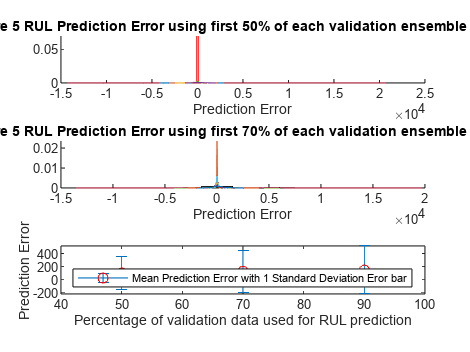

    [~, idx] = sort(abs(signalSlope), 'descend');
    sensorTrended = sort(idx(1:8))

## Ensemble trend

    nsample = 50;

tabella_errori =    -0.7442   -8.5610    0.8578   -1.7809   -2.8205   -7.8935   -1.7512   -7.2631  -12.8117   -3.7602   -6.4221  -30.0813         0         0
   15.0500 -116.3415    1.0298   -8.9977   26.9478         0         0         0         0         0         0         0         0         0
   51.5963  -24.2411  -28.4069   53.3415    1.3127   -1.5248   -5.1372         0         0         0         0         0         0         0
   -1.9569   -0.9258   15.3590   25.6569  -36.8559  -16.6931  -15.7479  -18.3553  -40.9497         0         0         0         0         0
  -46.3319         0         0         0         0         0         0         0         0         0         0         0         0         0
 -106.0828   20.4156    9.4156    3.4906  -22.4080         0         0         0         0         0         0         0         0         0


    helperPlotEnsemble(clusterTrainNormal{i,1}, sensorTrended, dataVariables, nsample)

## Costruzione degli Health Indicator

    %% health indicator trainData and validData from most trendy sensors
    figure
    for motore = 1:numel(clusterTrainNormal{i,1})
        data = clusterTrainNormal{i,1}{motore};
        rul = max(data.Time)-data.Time;
        data.health_condition = rul / max(rul);
        clusterTrainNormal{i,1}{motore} = data;

tabella_rmse =    10.5208
   53.9816
   31.4700
   23.0884
   46.3319
   49.5446


    
        plot(clusterTrainNormal{i,1}{motore}.health_condition)
        % title('trainData');
        ylabel("Health Condition");
        xlabel("Samples");
        hold on
    end
    
    figure
    for motore = 1:numel(clusterValidNormal{i,1})
        data = clusterValidNormal{i,1}{motore};
        rul = max(data.Time)-data.Time;
        data.health_condition = rul / max(rul);
        clusterValidNormal{i,1}{motore} = data;
    
        plot(clusterValidNormal{i,1}{motore}.health_condition)
        % title('validationData');
        ylabel("Health Condition");
        xlabel("Samples");

s = 1.0e+04 *

    0.0002    2.2579    0.0020    0.0013    0.0102    0.8096


        hold on
    end

score = 1.0e+04 *

    0.0006
    1.1317
    0.0026
    0.0018
    0.0074
    0.4073


Creazione di un **modello Lineare (!) **per l'indicatore di condizione unico

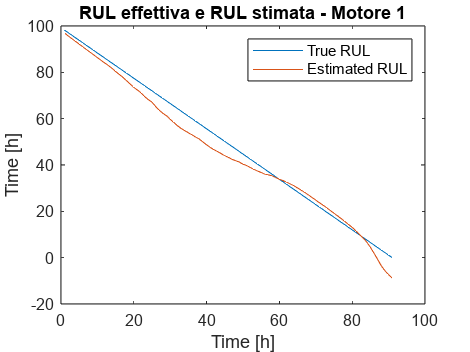

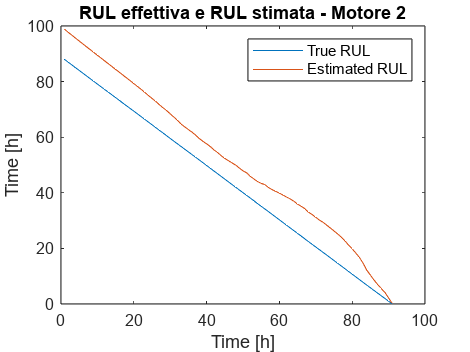

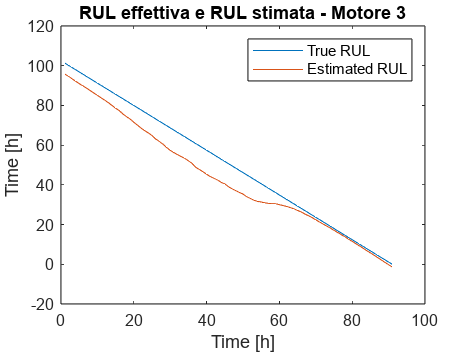

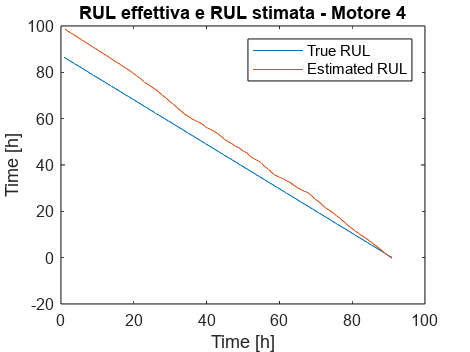

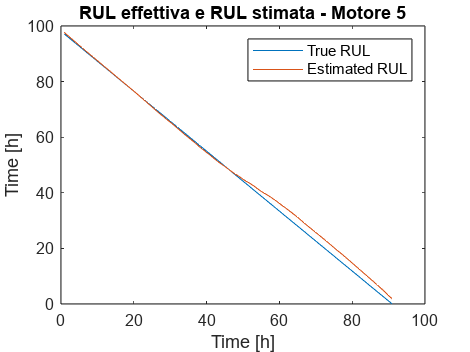

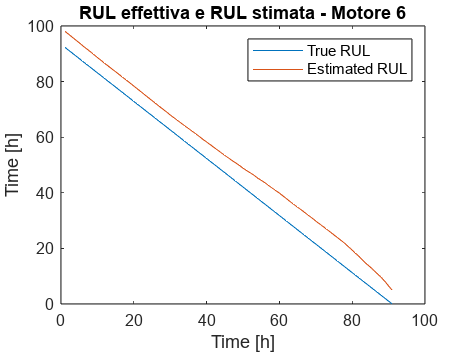

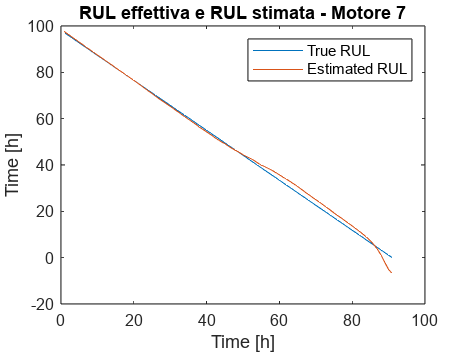

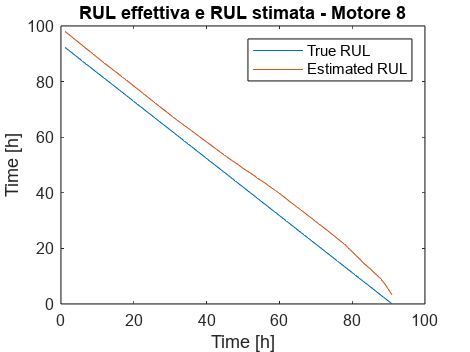

    %% fitting linear model for unified health indicator
    trainDataNormalizedUnwrap = vertcat(clusterTrainNormal{i,1}{:});
    
    sensorToFuse = dataVariables(sensorTrended);
    X = trainDataNormalizedUnwrap{:, cellstr(sensorToFuse)};
    y = trainDataNormalizedUnwrap.health_condition;
    regModel = fitlm(X,y);
    
    bias = regModel.Coefficients.Estimate(1)
    weights = regModel.Coefficients.Estimate(2:end)
    
    
    %% unified health condition
    trainDataFused{i,1} = cellfun( @(data) degradationSensorFusion(data, sensorToFuse, weights), clusterTrainNormal{i,1}, ...
        'UniformOutput', false);
    if i == 2
        trainDataFused{i,1}=trainDataFused{i,1}([1:2,4:end]);
    end 
 
    validationDataFused{i,1} = cellfun(@(data) degradationSensorFusion(data, sensorToFuse, weights), ...
        clusterValidNormal{i,1}, 'UniformOutput', false);
    
    figure
    for k = 1:length(trainDataFused{i,1})
        plot(trainDataFused{i,1}{k})
        % title('trainDataFused')
        xlabel('Samples')
        ylabel('Health Indicator')
        % title('Training Data')
        hold on
    end

    
    figure
    for k = 1:length(validationDataFused{i,1})
        plot(validationDataFused{i,1}{k})
        % title('validationDataFused')
        xlabel('Samples')
        ylabel('Health Indicator')
        % title('ValidationDataFused')
        hold on
    end
end

for k=1:height(sovraClustersTrain)
    lungh(k) = height(sovraClustersTrain{k,1});
end

maxMotore = max(lungh);

Eliminazione motore corrotto

% todo da rivedere per renderlo adattabile al clustering che da sempre
% risultati diversi
if i == 2
    sovraClustersTrain{i,1}=sovraClustersTrain{i,1}([1:2,4:end]);
end 

## Modello per RUL

AGGIUSTARE PARAMETRI

%% Build Similarity RUL Model

mdl = cell(height(trainDataFused),1);

for i = 1:height(mdl)
    mdl{i} = residualSimilarityModel(...
    'Method', 'poly2',...
    'Distance', 'euclidean',...
    'NumNearestNeighbors', Inf,...
    'Standardize', 1);

    fit(mdl{i}, trainDataFused{i,1});
end

% codice per eliminare gli health indicator divergenti
% for i = 1:height(trainDataFused)
%     for k=1:height(trainDataFused{i,1})
%         trainDataFused1{i,1}{k} = trainDataFused{i,1}{k,1}(end) < 0.5;
%     end
% end

% for i = 1:height(validationDataFused)
%     for k=1:height(validationDataFused{i,1})
%         len = height(validationDataFused{i,1}{k});
%         validationDataFused1{i,1}{k,1} = validationDataFused{i,1}{k,1}(end) < 1;
%     end
% end

## Calcolo RUL 

## Visualizzazione performance e statistiche RUNTIME

In questa sezione vengono mostrati i profili di degradazione con la RUL in RUNTIME.

Siano fissati tre istanti di tempo rispetto alla durata dei Validation Data:

- 50% della durata $\Rightarrow$ calcolo della stima RUL fino a questo momento

- 70% della durata $\Rightarrow$ calcolo della stima RUL fino a questo momento

- 90% della durata $\Rightarrow$ calcolo della stima RUL fino a questo momento

% pulizia variabili
clearvars -except mdl trainDataFused validationDataFused maxMotore

%% performance evaluation for test unit 

titolo = "K Nearest Neighbour Point - Unit ";

%mdl_cluster = mdl{2};

%valid = validationDataFused{2,1};

tabella_errori = zeros(height(trainDataFused), maxMotore);

for i = 1:6
    valid = validationDataFused{i,1};
    %valid = trainDataFused{i,1};
    mdl_cluster = mdl{i};

    for test_unit = 1:height(valid)
        breakpoint = [0.5, 0.7, 0.9];
        validationDataTmp = valid{test_unit}; 
        %validationDataTmp = valid;

50%

        bpidx = 1;
        validationDataTmp50 = validationDataTmp(1:ceil(end*breakpoint(bpidx)),:);
        trueRUL = length(validationDataTmp) - length(validationDataTmp50);
        [estRUL, ciRUL, pdfRUL] = predictRUL(mdl_cluster, validationDataTmp50);
        
        % figure
        compare(mdl_cluster, validationDataTmp50);
        title(titolo + test_unit + " - 50%")
        xlabel("Number of Samples")
        ylabel("Health indicator")
    
        
        helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)
        title("RUL Estimation Motore " + test_unit + " - 50%")

70%

        bpidx = 2;
        validationDataTmp70 = validationDataTmp(1:ceil(end*breakpoint(bpidx)), :);
        trueRUL = length(validationDataTmp) - length(validationDataTmp70);
        [estRUL,ciRUL,pdfRUL] = predictRUL(mdl_cluster, validationDataTmp70);
        
        % figure
        compare(mdl_cluster, validationDataTmp70);  
        title(titolo + test_unit + " - 70%")
        
        helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)
        title("RUL Estimation Motore " + test_unit + " - 70%")

90%

        bpidx = 3;
        validationDataTmp90 = validationDataTmp(1:ceil(end*breakpoint(bpidx)), :);
        trueRUL = length(validationDataTmp) - length(validationDataTmp90);
        [estRUL,ciRUL,pdfRUL] = predictRUL(mdl_cluster, validationDataTmp90);

        %estRUL = estRUL*90/3600;
        %trueRUL = trueRUL*90/3600;
        %pdfRUL = pdfRUL*90/3600;
        %ciRUL = ciRUL*90/3600;

        % figure
        compare(mdl_cluster, validationDataTmp90);  
        title(titolo + test_unit + " - 90%")
    
        helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)
        title("RUL Estimation Motore " + test_unit + " - 90%")
    

## Calcolo dell'errore sulla RUL

    % calcolo scostamento StimaRUL - trueRUL sull'intera simulazione
    
        numValidation = length(validationDataFused);
        numBreakpoint = length(breakpoint);
        error = zeros(numValidation, numBreakpoint);
    
        tmpData = valid{test_unit};
        % tmpData = valid;
        for bpidx = 1:numBreakpoint
            tmpDataTest = tmpData(1:ceil(end*breakpoint(bpidx)), :);
            trueRUL = length(tmpData) - length(tmpDataTest);
            [estRUL, ~, ~] = predictRUL(mdl_cluster, tmpDataTest);
            error(test_unit, bpidx) = estRUL - trueRUL;
        end

## Visualizzazione delle performance sull'intera simulazione

Stima della pdf nei tre istanti di tempo prima definiti

        [pdf50, x50] = ksdensity(error(:, 1));
        [pdf70, x70] = ksdensity(error(:, 2));
        [pdf90, x90] = ksdensity(error(:, 3));

Confronto tra le pdf ottenute e l'errore

        % figure
        ax(1) = subplot(3,1,1);
        hold on
    %     histogram(error(:, 1), 'BinWidth', 1500, 'Normalization', 'pdf')
        line([error(1) error(1)],[0 max(pdf50)],'Color','r','LineWidth',1.5)
        plot(x50, pdf50)
        hold off
        xlabel('Prediction Error')
        title("Motore " + test_unit + " RUL Prediction Error using first 50% of each validation ensemble member")
        
        ax(2) = subplot(3,1,2);
        hold on
        histogram(error(:, 2), 'BinWidth', 1500, 'Normalization', 'pdf')
        plot(x70, pdf70)
        hold off
        xlabel('Prediction Error')
        title("Motore " + test_unit + " RUL Prediction Error using first 70% of each validation ensemble member")    
        
        ax(3) = subplot(3,1,3);
        hold on
        histogram(error(:, 3), 'BinWidth', 1500, 'Normalization', 'pdf')
        plot(x90, pdf90)
        hold off
        xlabel('Prediction Error')
        title("Motore " + test_unit + " RUL Prediction Error using first 90% of each validation ensemble member")    
        % linkaxes(ax)

## Visualizzazione delle statistiche dell'errore

Il seguente grafico mostra l'andamento di mediana, 25° percentile, 75° percentile e valori massimi e minimi per ciascuno dei tre istanti di tempo: l'andamento ottimo deve convergere a zero.

        % figure
        boxplot(error, 'Labels', {'50%', '70%', '90%'})
        ylabel('Prediction Error')
        title("Motore " + test_unit + " Prediction error sui 3 istanti di tempo")

Calcolo del valore medio e della dev std

    % calcolo dev std e val med
        errorMean = mean(error);
        errorMedian = median(error);    
        errorSD = std(error);

Il seguente grafico mostra il valore medio $\pm$ dev std per ogni istante dei tre: i valori devono avere un andamento convergente a zero,

        % figure
        errorbar([50 70 90], errorMean, errorSD, '-o', 'MarkerEdgeColor','r')
        xlim([40, 100])
        xlabel('Percentage of validation data used for RUL prediction')
        ylabel('Prediction Error')
    %     title("Motore " + test_unit + " Valore medio e SD per i 3 istanti di tempo")
        legend('Mean Prediction Error with 1 Standard Deviation Eror bar', 'Location', 'south')
        
        tabella_errori(i, test_unit) = (trueRUL - estRUL) * 90/3600;
    end
end



tabella_errori

tabella_rmse = zeros(6,1);
for i = 1:6
    n(i) = nnz(tabella_errori(i,:));
    tabella_rmse(i) = sqrt((sum(nonzeros(tabella_errori(i,:)).^2))/n(i));
end

tabella_rmse
% sovrastimata = negativo
% sottostimata = positivo
for i = 1:6
    n(i) = nnz(tabella_errori(i,:));
    segno = zeros(n(i),1);
    segno = nonzeros(tabella_errori(i,:)) > 0;
    segno1 = zeros(n(i),1);
    for k = 1:length(segno)
        if segno(k) > 0
            segno1(k) = 1/13; % sottostimata
        else
            segno1(k) = 1/10;
        end
    end

    s(i) = sum(exp(segno1.*nonzeros(abs(tabella_errori(i,:))))-1)/n(i);
end

s

score = 0.5*tabella_rmse + 0.5*s'


Plot dei grafici per RUL Vera e Stimata (esempio Cluster 1) 

n_cluster = 1;

mdl_cluster = mdl{n_cluster};

breakpoint = (0.1:0.01:1)';

for motore = 1:length(validationDataFused{n_cluster})
%     breakpoint = [0.5, 0.7, 0.9];
    valid = validationDataFused{n_cluster,1}{motore};
    for bpidx = 1:length(breakpoint)
        
        validationDataTmp = valid;
        validationDataTmp50 = validationDataTmp(1:ceil(end*breakpoint(bpidx)),:);
        trueRUL(bpidx) = length(validationDataTmp) - length(validationDataTmp50);
        [estRUL(bpidx), ciRUL, pdfRUL] = predictRUL(mdl_cluster, validationDataTmp50);        
        
    end
    
    figure
    plot(trueRUL*90/3600);
    % plot(validationDataTmp)
    hold on
    plot(estRUL*90/3600)
    legend('True RUL','Estimated RUL')
    xlabel("Time [h]");
    ylabel("Time [h]");
    title("RUL effettiva e RUL stimata - Motore " + motore)
    hold off

end

## Helper Functions

function [mista] = creamista(X_dec,W_dec) 

    X_dec = timetable2table(X_dec);
    W_dec = timetable2table(W_dec);
    W_dec = W_dec(:,2:end);
    
    mista = [X_dec W_dec];
end

%% funzione per la decimazione dei dati e relativa verifica
% input: tabella da decimare e fattore di decimazione
% output: tabella decimata
% discostamneto massimo della media accettato 2%

function [newtable] = decimazione_dati(tabella,fattore_decim)

    nomiVariabili = tabella.Properties.VariableNames;
    dimensione = size(nomiVariabili);
    dimensione = dimensione(2);
    
    % creo la nuova tabella da riempire
    arr = decimate(double(tabella.(1)), fattore_decim);
    [row,~] = size(arr);
    tabella_decim = zeros(row,dimensione);
    
    
    % decimo i segnali della tabella originali e creo una nuova tabella con
    %i segnali decimati
    for i=1:dimensione
        originale = tabella.(i);
    
        % decimazione del segnale
        segnaleNew = decimate(double(originale),fattore_decim);
    
        % aggiungo il segnale decimato alla nuova tabella
        tabella_decim(:,i) = segnaleNew;
    end
    

    % creo la timetable con i segnali decimati
    identifico_tabella = nomiVariabili{1};
    if(strcmp('T24',identifico_tabella))
        X_s_dec_time = array2timetable(tabella_decim,'VariableNames',nomiVariabili, 'RowTimes', seconds(1:fattore_decim:size(tabella)));
        newtable = X_s_dec_time;
    elseif(strcmp('alt',identifico_tabella))
        W_tab_dec_dev = array2table(tabella_decim, 'VariableNames', nomiVariabili);
        newtable = W_tab_dec_dev;
        
    elseif(strcmp('Y',identifico_tabella))
        Y_tab_dec_dev = array2table(tabella_decim, 'VariableNames', {'Y'});
        newtable = Y_tab_dec_dev;
    elseif(strcmp('unit',identifico_tabella))
        A_dec = array2table(tabella_decim, 'VariableNames', nomiVariabili);
        newtable = A_dec; 
    else
        T_dec = array2table(tabella_decim, 'VariableNames', nomiVariabili);
        newtable = T_dec; 
    end
end

function dataFused = degradationSensorFusion(data, sensorToFuse, weights)
% Combine measurements from different sensors according 
% to the weights, smooth the fused data and offset the data
% so that all the data start from 1

    % Fuse the data according to weights
    dataToFuse = data{:, cellstr(sensorToFuse)};
    dataFusedRaw = dataToFuse*weights;
    
    % Smooth the fused data with moving mean
    stepBackward = 10;
    stepForward = 10;
    dataFused = movmean(dataFusedRaw, [stepBackward stepForward]);
    
    % Offset the data to 1
    dataFused = dataFused + 1 - dataFused(1);
end

%% creazione della tabella da importare nel Diagnostic Feature Designer

function [motore] = GeneraEnsabletable2(Hs,X_dec)
    
    flag_stato = 1;
    intervalli = 1;
    valorePrima = 1;
    motore = table();
    dimensionetabella = length(Hs);
    
    % intervalli = [1 4814 7800 16000 ... ]
    % 4814 l'istante dove il motore 1 smette di funzionare bene
    % 7800 l'istante dove il motore 2 inizia a funzionare 
    % 16000 l'istante dove il motore 2 smette di funzionare bene
    
    for istante=1:dimensionetabella
        
        valore = Hs(istante);
        if (valore - valorePrima) == 0 
            valorePrima = valore;
            continue
        elseif (valore - valorePrima) == 1
            intervalli = [intervalli, istante];
        end
        
      valorePrima = valore;
    end
    
    intervalli = [intervalli, dimensionetabella];
    
    % scorriamo gli intervalli 
    dimensione_intervalli = length(intervalli);
    
    for i = 1:dimensione_intervalli  
        if i == dimensione_intervalli
            break
        elseif i == 1
            riga11 = X_dec(intervalli(i):intervalli(i+1),:);
            motore = table({riga11},'VariableNames',{'X_S'});
        elseif i == dimensione_intervalli-1
            riga11 = X_dec(intervalli(i):intervalli(i+1),:);
            riga = table({riga11}, 'VariableNames',{'X_S'});
            motore = [motore; riga];
        else
            dati = X_dec(intervalli(i):intervalli(i+1),:);
            riga = table({dati}, 'VariableNames',{'X_S'});
            motore = [motore; riga];
        end
    end
end


function [] = helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)

    p = 125/5000;
    time = 0:p:125-p; % 125 max number of hours
    ora = 90/3600;

    ci1 = ceil(ciRUL(1))*ora;
    ci2 = ceil(ciRUL(2))*ora;
    yMax = max(pdfRUL.ProbabilityDensity);
    xArea = [ci1 ci2 ci2 ci1];
    yArea = [0 0 yMax yMax];

    % figure
    plot(pdfRUL.RUL*ora,pdfRUL.ProbabilityDensity,'b')
    title('RUL Estimation')
    xlabel('Hours')
    ylabel('Probability Density')
    hold on
    line([trueRUL*ora trueRUL*ora],[0 yMax],'Color','r','LineWidth',1.5)
    line([estRUL*ora estRUL*ora],[0 yMax],'Color','g','LineWidth',1.5)
    
    patch(xArea,yArea,'yellow','FaceAlpha',0.3)

    legend('pdfRUL','trueRUL','estRUL','Confidence interval 90%')
    hold off

end

function [X_s_time,W_tab_dev,Y_tab_dev,A_tab_dev, T_tab_dev ...
        ,X_s_tab_test, W_tab_test, Y_tab_test, ...
        A_tab_test, T_tab_test ] = importoTabelle(num_dataset, user)

    fileList = {'N-CMAPSS_DS01-005.h5', 'N-CMAPSS_DS02-006.h5', 'N-CMAPSS_DS03-012.h5', 'N-CMAPSS_DS04.h5', 'N-CMAPSS_DS05.h5', 'N-CMAPSS_DS06.h5', 'N-CMAPSS_DS07.h5', 'N-CMAPSS_DS08a-009.h5', 'N-CMAPSS_DS08c-008.h5', 'N-CMAPSS_DS08d-010.h5'};
    
    % set path
    if strcmp(user,"Ado")
        path = '/Users/adolfocafaro/università/ManutenzioneRobotica/D - PHM2021 Data  Challenge - Dataset/data_set/';
    elseif strcmp(user,"Andrea")
        path = 'D:/Dataset_università/Manutenzione_preventiva_per_la_robotica_e_l''automazione_intelligente/data_set/';
    elseif strcmp(user,"Oleg")
        path = 'E:\data_set\';
%     elseif strcmp(user,"Giorgio")
%         path = %path Giorgio
    else
        path = strcat(uigetdir,'\');
    end
    
    filename = string(append(path,fileList(num_dataset)));
    
    W_dev = h5read(filename, '/W_dev');
    X_s_dev = h5read(filename, '/X_s_dev');
    %X_v_dev = h5read(filename, '/X_v_dev');
    T_dev = h5read(filename, '/T_dev');
    Y_dev = h5read(filename, '/Y_dev');
    A_dev = h5read(filename, '/A_dev');
    
    W_var = strrep(cellstr(h5read(filename, '/W_var'))',' ','');
    X_s_var = h5read(filename, '/X_s_var')';
    %X_v_var = strrep(cellstr(h5read(filename, '/X_v_var'))',' ','');
    T_var = strrep(cellstr(h5read(filename, '/T_var'))',' ','');
    A_var = strrep(cellstr(h5read(filename, '/A_var'))',' ','');
    
    % creare tabelle DEV
    W_tab_dev = array2timetable(W_dev', 'VariableNames', W_var, 'RowTimes', seconds(1:size(W_dev')));
    X_s_time = array2timetable(X_s_dev', 'VariableNames', X_s_var, 'RowTimes', seconds(1:size(X_s_dev')));    
    %     X_v_tab_dev = array2table(X_v_dev', 'VariableNames', X_v_var);
    T_tab_dev = array2table(T_dev', 'VariableNames', T_var);
    Y_tab_dev = array2table(Y_dev', 'VariableNames', {'Y'});
    A_tab_dev = array2table(A_dev', 'VariableNames', A_var);
    
    
    % andiamo a modificare i nomi delle variabili togliendo gli "spazi"
    stringanomi = X_s_time.Properties.VariableNames;
    carattere_male = strrep(stringanomi(3),'T48','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    X_s_time.Properties.VariableNames = stringanomi;
    
    stringanomi = W_tab_dev.Properties.VariableNames;
    carattere_male = strrep(stringanomi(1),'alt','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    W_tab_dev.Properties.VariableNames = stringanomi;
    
    stringanomi = A_tab_dev.Properties.VariableNames;
    carattere_male = strrep(stringanomi(1),'unit','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    A_tab_dev.Properties.VariableNames = stringanomi;
    
    stringanomi = T_tab_dev.Properties.VariableNames;
    carattere_male = strrep(stringanomi(1),'fan_eff_mod','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    T_tab_dev.Properties.VariableNames = stringanomi;
    
    W_test = h5read(filename, '/W_test');
    X_s_test = h5read(filename, '/X_s_test');
    % X_v_test = h5read(filename, '/X_v_test');
    T_test = h5read(filename, '/T_test');
    Y_test = h5read(filename, '/Y_test');
    A_test = h5read(filename, '/A_test');
    
     % creare tabelle DEV
    W_tab_test = array2timetable(W_test', 'VariableNames', W_var, 'RowTimes', seconds(1:size(W_test')));
    X_s_tab_test = array2timetable(X_s_test', 'VariableNames', X_s_var, 'RowTimes', seconds(1:size(X_s_test')));    
    %X_v_tab_test = array2table(X_v_test', 'VariableNames', X_v_var);
    T_tab_test = array2table(T_test', 'VariableNames', T_var);
    Y_tab_test = array2table(Y_test', 'VariableNames', {'Y'});
    A_tab_test = array2table(A_test', 'VariableNames', A_var);
    
    
    % andiamo a modificare i nomi delle variabili togliendo gli "spazi"
    stringanomi = X_s_tab_test.Properties.VariableNames;
    carattere_male = strrep(stringanomi(3),'T48','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    X_s_tab_test.Properties.VariableNames = stringanomi;
    
    stringanomi = W_tab_test.Properties.VariableNames;
    carattere_male = strrep(stringanomi(1),'alt','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    W_tab_test.Properties.VariableNames = stringanomi;
    
    stringanomi = A_tab_test.Properties.VariableNames;
    carattere_male = strrep(stringanomi(1),'unit','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    A_tab_test.Properties.VariableNames = stringanomi;
    
    stringanomi = T_tab_test.Properties.VariableNames;
    carattere_male = strrep(stringanomi(1),'fan_eff_mod','');
    stringanomi = strrep(stringanomi,carattere_male,'');
    T_tab_test.Properties.VariableNames = stringanomi;

end

function rowNormalized = localNormalize(row, conditionIdx, dataIdx, centers, centerstats)
% Normalization operation for each row.

    % Get the operating points and sensor measurements
    ops = row(1, conditionIdx);
    sensor = row(1, dataIdx);
    
    % Find which cluster center is the closest
    dist = sum((centers - ops).^2, 2);
    [~, idx] = min(dist);
    
    % Normalize the sensor measurements by the mean and standard deviation of the cluster.
    % Reassign NaN and Inf to 0.
    rowNormalized = (sensor - centerstats.Mean{idx, :}) ./ centerstats.SD{idx, :};
    rowNormalized(isnan(rowNormalized) | isinf(rowNormalized)) = 0;
end

function data = regimeNormalization(data, centers, centerstats)
    % Perform normalization for each observation (row) of the data
    % according to the cluster the observation belongs to.
    
    % attenzione!! la tabella dei dati che vado a normalizzare ha 18
    % colonne in quanto non considero la colonna tempo.
    conditionIdx = 15:18;
    dataIdx = 1:14;
    
    % Perform row-wise operation
    data{:, 2:15} = table2array(...
        rowfun(@(row) localNormalize(row, conditionIdx, dataIdx, centers, centerstats), ...
        data(:,2:end), 'SeparateInputs', false));
end

function [] = helperPlotEnsemble(trainDataNormalized, sensorTrended, dataVariables, nsample)

    colonne = sensorTrended(3:6)+1;
    [row,~] = size(trainDataNormalized);
    
    % figure
    title('Trend sensori')
    for i = 1:length(colonne)
        subplot(4,1,i)
        for j = 1:row
            hold on
            y = trainDataNormalized{j,1}.(colonne(i))(1:nsample:end);
            plot(y)
            xlabel('Time')
            ylabel(string(dataVariables(i)))
            title(strcat('Trend sensore ',string(dataVariables(i))))
        end
        hold off
    end
    hold off
end
